# Advanced plotting & visualizations (NHANES) 

## Setup

**Today’s theme**: turn a real, messy dataset into clear informative figures. 

**Dataset**: NHANES (CDC survey; Kaggle mirror)

We will build a teaching** subset** of ~1,000 adults. 

## Learning goals

- Understand why NHANES is split into multiple tables (demographics / exams / labs / questionnaires)

- Merge tables using the participant key `SEQN` 

- Make plots that are **readable and informative**: labels, units, legends, and consistent styling

**Reminder**: In research, NHANES uses survey weights/strata. In this plotting lecture we use an unweighted sample to focus on visualization.

**MATLAB Online warning you might see: **If you see browser messages like `SceneModel error ... Cannot read properties of undefined`, that is a MATLAB Online rendering warning (not a bug in your code). Your figures still render and `exportgraphics` will still save them. Optional workaround: force a simpler renderer (may look slightly different):  `set(groot,'DefaultFigureRenderer','painters')`

## `Placing Data and Pre-setting Axes`

clear; close all; clc;

% Put your files in one folder and list it here:
% demographic.csv, examination.csv, questionnaire.csv, labs.csv, diet.csv, medications.csv
DATA_DIR = fullfile("data");

rng(2);

set(groot, "defaultFigureColor", "w");
set(groot, "defaultAxesFontSize", 13);
set(groot, "defaultAxesLineWidth", 1);
set(groot, "defaultLineLineWidth", 2);

## **Load and merge the core NHANES tables**

NHANES is not a single big spreadsheet. Instead, it is split into *component *files, each focusing on a different aspects of the people being studied:

- **Demographics**: age, sex, basic identifiers

- **Examination**: measured height/weight, BMI, blood pressure

- **Questionnaire**: self-reported behaviors such as smoking

- **Laboratory**: blood tests such as total cholesterol

Each row in these component tables describes one person, and the row is labeled by a shared participant ID called `SEQN`. This ID is the “bridge” that lets us reconnect the components across the different files.

To do that, we use **joins**:

- A *join* is the table version of “match rows that have the same key.”

- For example, when we join Demographics and Examination on `SEQN`, the row for `SEQN = 12345` in Demographics is matched with the row for `SEQN = 12345` in Examination, and their columns are combined into one wider row.

In this lecture we use **left joins** (MATLAB’s `outerjoin(...,"Type","left")`):

- The **left** table is Demographics, which we treat as our “master list” of people.

- A left join keeps *everyone* from the demographics table, even if they were missing a blood pressure reading or cholesterol lab.

- If a participant has no matching row in a component table (i.e. non-demographic table), the joined columns show up as `NaN` (missing). 

Our goal in this cell is to:

- Load the four core component CSVs (demographic, examination, questionnaire, labs).

- Merge them into a single `Core` table with one row per adult participant and nice variable names (Age, Sex, BMI, blood pressure, smoking, cholesterol).

- Draw a random ~1000-person subset for fast plotting.

This gives us a tidy, person-level table that the rest of the lecture can treat as “just data,” without worrying about the NHANES file layout.

function T = readKaggleCsv(path, selectedVars)

    if nargin < 2, selectedVars = []; end

    opts = detectImportOptions(path);
    opts.VariableNamingRule = "preserve";
    if ~isempty(selectedVars)
        % Only keep vars that exist
        present = intersect(string(opts.VariableNames), string(selectedVars), "stable");
        opts.SelectedVariableNames = cellstr(present);
    end

    encs = ["UTF-8","ISO-8859-1","windows-1252"];
    lastErr = [];
    for e = encs
        try
            opts.Encoding = e;
            T = readtable(path, opts);
            return
        catch ME
            lastErr = ME;
        end
    end
    rethrow(lastErr);
end

function y = recodeYesNo(x)
    y = NaN(size(x));
    y(x==1) = 1;
    y(x==2) = 0;
end

function m = meanBP(T, names)
% Compute mean across available BP readings; treat zeros as missing.
    names = string(names);
    present = intersect(names, string(T.Properties.VariableNames), "stable");
    if isempty(present)
        m = NaN(height(T),1);
        return
    end
    A = T{:, present};
    A(A==0) = NaN;
    m = mean(A, 2, "omitnan");
end

function f = newFig(figName, sz)
    if nargin < 2, sz = [980 520]; end
    f = figure("Name", figName, "Units","pixels", "Position",[80 80 sz(1) sz(2)]);
end

function subtitleIfAvailable(txt)
    if exist("subtitle","file") == 2
        subtitle(txt);
    else
        % fallback: do nothing
    end
end

function [binIdx, centers] = bin1(x, edges)
% Discretize x into edges and return bin centers
    edges = edges(:)';
    centers = (edges(1:end-1) + edges(2:end))/2;
    binIdx = discretize(x, edges);

Core teaching table ready (adult sample):


    % keep only points inside bins; return 1-based indices with NaNs removed
end

    SEQN     Age     Sex      BMI     Height_cm    Weight_kg    SysBP     DiaBP     SmokeEver    TotalChol    Obese     BMIclass 
    _____    ___    ______    ____    _________    _________    ______    ______    _________    _________    _____    __________

    78040    59     Female    22.4      160.3         57.5      148.67    79.333        0           237       false    Normal    
    73806    63     Male      32.2      184.2        109.2      131.33        58        1           220       true     Obese     
    79210    25     Male      20.7      168.8         59.1      114.67 

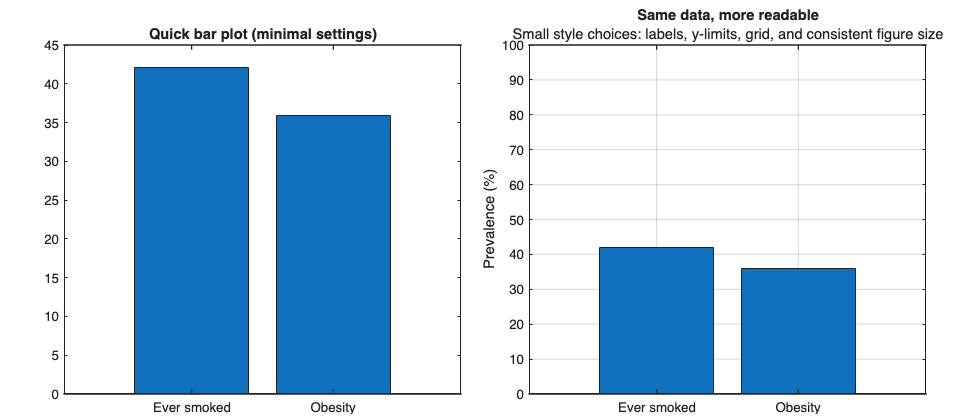


coreFiles = ["demographic.csv","examination.csv","questionnaire.csv","labs.csv"];

missingFiles = coreFiles(~isfile(fullfile(DATA_DIR, coreFiles)));
if ~isempty(missingFiles)
    error("Missing required NHANES CSV(s): %s\nPut the Kaggle CSVs in: %s", ...
          strjoin(missingFiles, ", "), DATA_DIR);
end

% Read the variables
demo = readKaggleCsv(fullfile(DATA_DIR,"demographic.csv"), ...
    ["SEQN","RIDAGEYR","RIAGENDR"]);

exam = readKaggleCsv(fullfile(DATA_DIR,"examination.csv"), ...
    ["SEQN","BMXBMI","BMXHT","BMXWT", ... % BMI, height, weight
     "BPXSY1","BPXSY2","BPXSY3","BPXSY4", ... % systolic BP readings
     "BPXDI1","BPXDI2","BPXDI3","BPXDI4"]); % diastolic BP readings

quest = readKaggleCsv(fullfile(DATA_DIR,"questionnaire.csv"), ...
    ["SEQN","SMQ020"]); % ever smoked (yes/no)

labs = readKaggleCsv(fullfile(DATA_DIR,"labs.csv"), ...
    ["SEQN","LBXTC"]); % total cholesterol

% Perform a sequence of LEFT JOINS on SEQN.
% everyone in the left table is kept, and columns from the right table are
% added when a matching SEQN exists (otherwise we see NaN).
T = outerjoin(demo, exam,  "Keys","SEQN", "MergeKeys",true, "Type","left");
T = outerjoin(T,    quest, "Keys","SEQN", "MergeKeys",true, "Type","left");
T = outerjoin(T,    labs,  "Keys","SEQN", "MergeKeys",true, "Type","left");

Core = table();
Core.SEQN      = T.SEQN;
Core.Age       = T.RIDAGEYR;
Core.Sex       = categorical(T.RIAGENDR, [1 2], ["Male","Female"]);
Core.BMI       = T.BMXBMI;
Core.Height_cm = T.BMXHT;
Core.Weight_kg = T.BMXWT;

Core.SysBP = meanBP(T, ["BPXSY1","BPXSY2","BPXSY3","BPXSY4"]);
Core.DiaBP = meanBP(T, ["BPXDI1","BPXDI2","BPXDI3","BPXDI4"]);

Core.SmokeEver = recodeYesNo(T.SMQ020);

Core.TotalChol = T.LBXTC;

% Focus on adults only; for this plotting lecture we treat the sample as
% unweighted so that we can focus on figure design rather than survey

% statistics.
Core = Core(Core.Age >= 18, :);

% Remove rows that are missing the core demographic variables we rely on, 
% then take a random subset of up to 1000 adults.
Core = rmmissing(Core, "DataVariables", ["Age","Sex","BMI"]);
n = min(1000, height(Core));
Core = Core(randperm(height(Core), n), :);

% Add a couple of derived fields that will be convenient in downstream
% plots (binary obesity flag and BMI category).
Core.Obese = Core.BMI >= 30;
Core.BMIclass = discretize(Core.BMI, [-Inf 18.5 25 30 Inf], ...
    "categorical", {'Underweight','Normal','Overweight','Obese'});

disp("Core teaching table ready (adult sample):");

disp(head(Core));

## Plotting defaults: make figures readable by construction

Before we worry about fancy visualizations, it helps to lock in a few simple plotting options. The idea is that most figures we want to set some "ground rules" for our plots so that they are “good enough for slides” as soon as they appear, without a lot of tweaking. 

**In this section we will**:

- Use a consistent figure size so axis labels and tick marks are readable on a projector.

- Use `tiledlayout` when we need multiple panels, so the spacing and shared titles are handled cleanly.

- Keep titles short and move extra context into subtitles or surrounding text.

- Work with graphics handles (`f = figure; ax = gca;`) so that we can tweak fonts and line widths in a targeted way when needed.

**A bar plot is a good choice when**:

- The x-axis is **categorical** (e.g., BMI classes, sex, age group, treatment arm).

- The height of each bar represents a **summary statistic** for that category (count, mean, prevalence, total, etc.), not the raw data points.

- You care about **comparing levels** across categories, not seeing the detailed distribution within each category.

Typical examples**:**

- Number of participants in each BMI category.

- Average cholesterol by age decade.

- Prevalence of “ever smoked” by sex.

**Bar plots are less appropriate for:**

- Raw time series or ordered numeric variables (a line plot usually communicates patterns more clearly there).

- Detailed shapes of distributions (histograms, density plots, boxplots, or violin plots are usually better).

- Situations where uncertainty matters but is not shown (bar height without error bars can be misleading).

In this demo, we use a simple prevalence example to contrast “default” bar plots with slightly more deliberate styling (labels, y-limits, grid, and layout). Make sure to focus on how the design choices affect readability. 

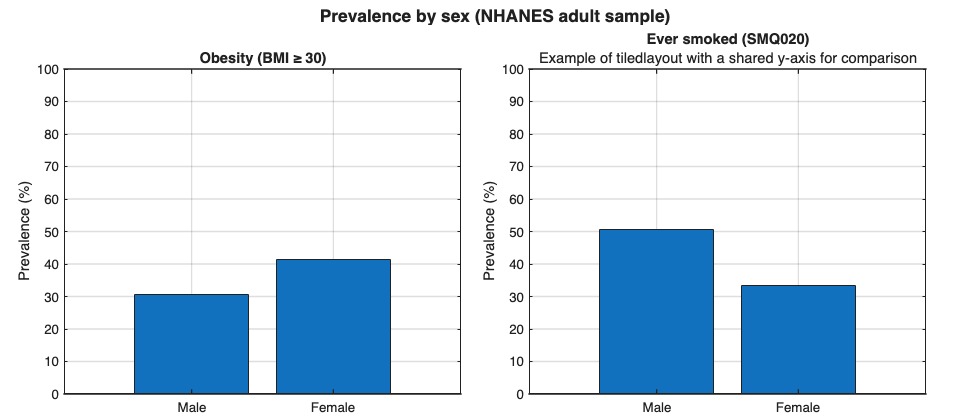

%% Step 2 — Plotting style helpers: bar plot example

% To illustrate the effect of basic plotting choices, we start with a very
% simple summary: the prevalence of obesity and "ever smoked" in the adult
% NHANES sample. We will:
% 1) Make a quick bar plot with almost no styling (what you might get if
% you just wrote a one-liner).
% 2) Make a second version with small improvements: clear labels, fixed
% y-limits, grid, and a legend-friendly title.

pObese = 100 * mean(Core.Obese, "omitnan");

pSmoke = 100 * mean(Core.SmokeEver == 1, "omitnan");

cats = categorical(["Obesity","Ever smoked"]);
vals = [pObese, pSmoke];

f = newFig("Style demo: prevalence bar plot", [980 420]);
tl = tiledlayout(f, 1, 2, "Padding","compact", "TileSpacing","compact");

% Left panel: minimal/default-style bar plot.
nexttile;
bar(cats, vals);
title("Quick bar plot (minimal settings)");

% Right panel: same data, but with a few deliberate style choices.
nexttile;
bar(cats, vals);
ylabel("Prevalence (%)");
ylim([0 100]);
grid on;
title("Same data, more readable");
set(gca, "XTickLabelRotation", 0);

subtitleIfAvailable("Small style choices: labels, y-limits, grid, and consistent figure size");

%% Prevalence by sex: using tiledlayout and shared y-axis

% Next, we take the same idea (prevalence of obesity and "ever smoked") and
% look at it by sex. This gives a natural example for using tiledlayout to
% make a small set of related panels with a shared y-axis, which makes
% comparisons much easier for the viewer.

G = groupsummary(Core, "Sex", "mean", ["Obese","SmokeEver"]);

f = newFig("Prevalence by sex", [980 420]);
tl = tiledlayout(f, 1, 2, "Padding","compact", "TileSpacing","compact");

nexttile;
bar(G.Sex, 100 * G.mean_Obese);
ylabel("Prevalence (%)");
ylim([0 100]);
grid on;
title("Obesity (BMI ≥ 30)");

nexttile;
bar(G.Sex, 100 * G.mean_SmokeEver);
ylabel("Prevalence (%)");
ylim([0 100]);
grid on;
title("Ever smoked (SMQ020)");

title(tl, "Prevalence by sex (NHANES adult sample)", "FontWeight","bold");
subtitleIfAvailable("Example of tiledlayout with a shared y-axis for comparison");

## Histograms: empirical distributions (shape matters)

Histograms are the basic tool for answering “what values are common?” and “how are they spread out?”. They show you rough distributional shape: center, spread, skewness, and whether there are multiple modes or obvious outliers.

In this section we use histograms to look at BMI, systolic blood pressure, and total cholesterol in our adult NHANES sample.

**Good habits when using histograms**

- Think about the **question** before you pick a bin width.  

- For BMI, bins of size 1 kg/m² are easy to interpret.  

- For systolic blood pressure, 5 mmHg bins line up with familiar clinical cutoffs.

- Label axes with **units **and **meaningful titles** (e.g. “Systolic blood pressure (mmHg)” rather than just “BP”).

- Use **reference lines** to mark thresholds that matter for interpretation: BMI 25/30, BP 120/140, cholesterol 200/240.

- Decide whether you care about **raw counts** or **relative frequencies**.  

- `Normalization="count"` shows how many people fall in each bin.  

- `Normalization="probability"` makes the bar heights add up to 1, so the y-axis is directly comparable across variables and subsets.

**When to use histograms**

- You want a quick sense of the distribution of a continuous variable.  

- You care about the **shape** (e.g. are high values rare or common?) rather than just the mean and standard deviation. 

- You have enough data that binning makes sense (with very small samples, a dot plot or strip chart is often clearer).

**When not to use histograms**

- Comparing many groups on the same plot can get messy; side-by-side histograms or boxplots may communicate relative shifts more clearly.  

- For time series, or variables with a natural order where you care about trends, a line plot is usually more informative.

In the code below we pick bin widths that line up with interpretable units and overlay reference lines for commonly used clinical cutoffs.

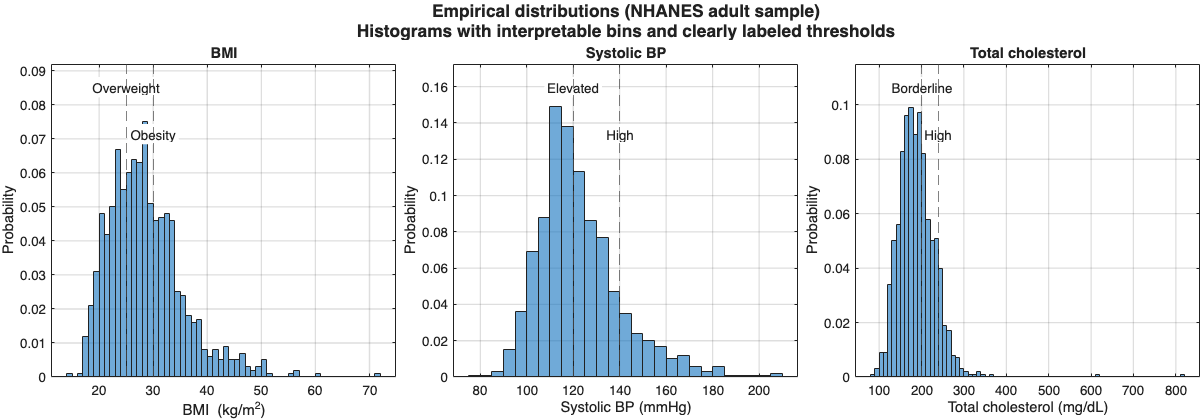

%% Histograms: distributions of BMI, BP, and cholesterol

bwidthBMI  = 1;
bwidthSys  = 5;
bwidthChol = 10;

f = newFig("Histograms", [1200 420]);
tl = tiledlayout(f, 1, 3, "TileSpacing","compact");
tl.Padding = "tight";

% BMI
nexttile;
h = histogram(Core.BMI, "BinWidth", bwidthBMI, "Normalization","probability");
xlabel("BMI (kg/m^2)");
ylabel("Probability");
grid on;
title("BMI", "FontWeight","bold");

% Create space on the top
yl = ylim;
ylim([0, yl(2)*1.15]);

% Threshold lines
xline(25, "--", "Color",[0.3 0.3 0.3]);
xline(30, "--", "Color",[0.3 0.3 0.3]);
yl = ylim;
text(25, yl(2)*0.95, "Overweight", ...
    "HorizontalAlignment","center", "VerticalAlignment","top", ...
    "BackgroundColor","w", "Margin",2, "EdgeColor","none");
text(30, yl(2)*0.80, "Obesity", ...
    "HorizontalAlignment","center", "VerticalAlignment","top", ...
    "BackgroundColor","w", "Margin",2, "EdgeColor","none");

% Systolic BP
nexttile;
h = histogram(Core.SysBP, "BinWidth", bwidthSys, "Normalization","probability");
xlabel("Systolic BP (mmHg)");
ylabel("Probability");
grid on;
title("Systolic BP", "FontWeight","bold");

yl = ylim;
ylim([0, yl(2)*1.15]);

xline(120, "--", "Color",[0.3 0.3 0.3]);
xline(140, "--", "Color",[0.3 0.3 0.3]);

yl = ylim;
text(120, yl(2)*0.95, "Elevated", ...
    "HorizontalAlignment","center", "VerticalAlignment","top", ...
    "BackgroundColor","w", "Margin",2, "EdgeColor","none");
text(140, yl(2)*0.80, "High", ...
    "HorizontalAlignment","center", "VerticalAlignment","top", ...
    "BackgroundColor","w", "Margin",2, "EdgeColor","none");

% Total Cholestorol
nexttile;
if any(~isnan(Core.TotalChol))
    h = histogram(Core.TotalChol, "BinWidth", bwidthChol, "Normalization","probability");
    xlabel("Total cholesterol (mg/dL)");
    ylabel("Probability");
    grid on;
    title("Total cholesterol", "FontWeight","bold");

    yl = ylim;
    ylim([0, yl(2)*1.15]);

    xline(200, "--", "Color",[0.3 0.3 0.3]);
    xline(240, "--", "Color",[0.3 0.3 0.3]);
    yl = ylim;
    text(200, yl(2)*0.95, "Borderline", ...
        "HorizontalAlignment","center", "VerticalAlignment","top", ...
        "BackgroundColor","w", "Margin",2, "EdgeColor","none");
    text(240, yl(2)*0.80, "High", ...
        "HorizontalAlignment","center", "VerticalAlignment","top", ...
        "BackgroundColor","w", "Margin",2, "EdgeColor","none");
else
    axis off;
    text(0.05, 0.5, "Total cholesterol (LBXTC) not available", "Units","normalized");
end

% We add the title at the end once the figure is complete
title(tl, { ...
    'Empirical distributions (NHANES adult sample)', ...
    'Histograms with interpretable bins and clearly labeled thresholds' ...
}, "FontWeight","bold");

## Scatter plots

Scatter plots are the basic tool for answering “how do two variables move together?”. In this section, we plot systolic blood pressure against age, and then use color to encode BMI as a third variable. This gives us both the overall direction of the relationship and a sense of individual variability.

### **Good habits for scatter plots**

- Pick two clear variables for the axes. Here, age is the explanatory variable (x-axis) and systolic blood pressure is the response (y-axis).

- **Use transparency and small marker size when there are tons of points, so individual points remain visible.**

- Use color to represent a third continuous variable such as BMI or cholesterol. Always include a labeled colorbar so viewers know what the colors mean.

- Add a simple trend line, such as a linear fit, when you want to show the average direction of the relationship. 

### **When scatter plots work well**

Scatter plots are useful when you want to visualize pattern *and* variability at the same time. For example, blood pressure may rise with age on average, but with a wide range of values at any given age. Scatter plots also help reveal nonlinear patterns, clusters, and outliers that would be hidden by summary statistics alone.

### **Scatter plot 1: Systolic BP vs Age with BMI encoded by color**

This plot asks whether systolic blood pressure tends to rise with age. The individual points show a wide amount of person-to-person variability at every age, but the overall visual pattern slopes upward: older adults are more likely to have higher systolic BP. The color scale adds BMI as a third variable, which helps us see whether heavier individuals cluster at higher blood pressures. The color gradient is mostly mixed throughout, suggesting that age explains more of the variation in systolic BP than BMI does (at least in this simple visual summary). The fitted line provides a quick model of the average relationship, without hiding the scatter.

### **Scatter plot 2: BMI vs Age, with sex encoded by color**

Here the x-axis remains age, but we switch the third variable to a categorical grouping (male vs female). Coloring by group rather than a continuous scale separates the two populations cleanly and shows that the male and female distributions overlap heavily at all ages. There is no obvious upward or downward trend in BMI across age in this adult sample, and neither sex shows a dramatically different pattern. In other words, the grouping does not reveal a strong age to BMI trend.

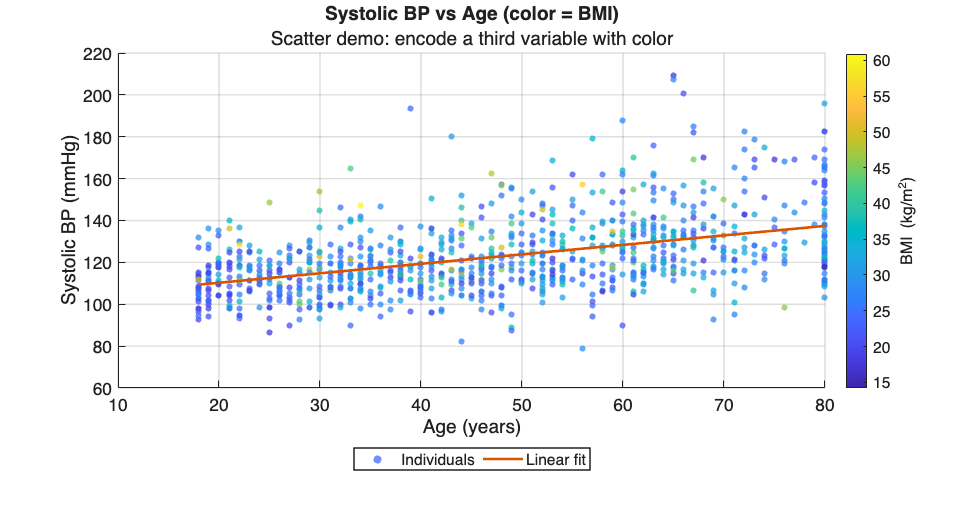

%% Scatter plots: Age vs systolic BP with BMI as color

% For scatter plots we want complete cases for the variables we actually
% show: age, systolic BP, and BMI (used for color).
T1 = rmmissing(Core, "DataVariables", ["Age","SysBP","BMI"]);

f = newFig("SysBP vs Age", [980 520]);

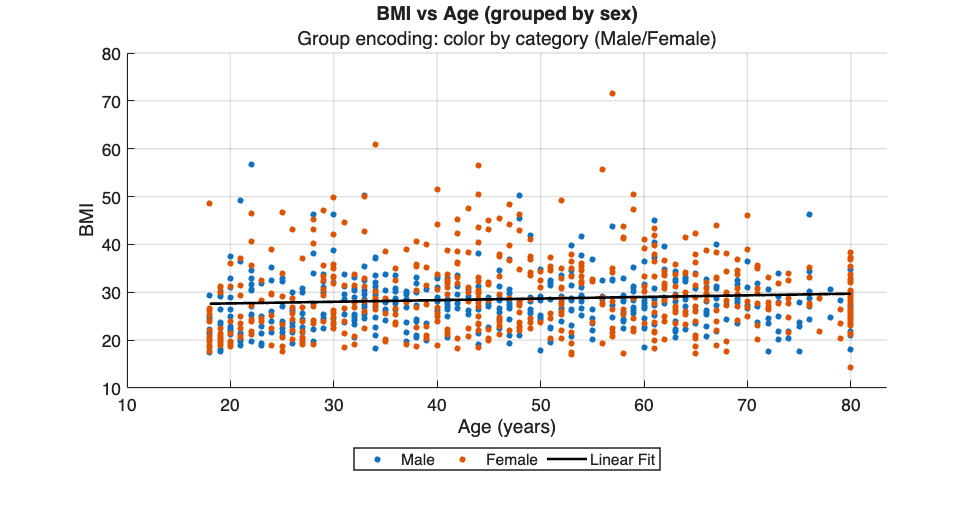


% Basic scatter: each point is one participant, x = Age, y = SysBP,
% color = BMI. Add some transparency when dense clustering of points. 
scatter(T1.Age, T1.SysBP, 22, T1.BMI, ...
    "filled", "MarkerFaceAlpha", 0.75);
xlabel("Age (years)");
ylabel("Systolic BP (mmHg)");
grid on;
title("Systolic BP vs Age (color = BMI)", "FontWeight","bold");
subtitleIfAvailable("Scatter demo: encode a third variable with color");

cb = colorbar;
cb.Label.String = "BMI (kg/m^2)";

hold on;


% Add a simple linear trend line to summarize the average relationship
% between age and systolic BP. This line should guide the eye, not replace
% looking at the cloud of points.
mdl = fitlm(T1.Age, T1.SysBP);
xg = linspace(min(T1.Age), max(T1.Age), 200)';
yg = predict(mdl, xg);
plot(xg, yg, "LineWidth", 2);

hold off;

legend({"Individuals","Linear fit"}, ...
    "Location","southoutside", "Orientation","horizontal");

drawnow;

% BMI vs Age grouped by Sex
newFig("BMI vs Age (by Sex)", [980 520]);
gscatter(Core.Age, Core.BMI, Core.Sex, [], ".", 14);
mdl = fitlm(Core.Age, Core.BMI);
hold on
xg = linspace(min(Core.Age), max(Core.Age), 200)';
plot(xg, predict(mdl, xg), "k-", "LineWidth", 2);
xlabel("Age (years)"); ylabel("BMI");
title("BMI vs Age (grouped by sex)", "FontWeight","bold");
subtitleIfAvailable("Group encoding: color by category (Male/Female)");
grid on
legend({"Male", "Female", "Linear Fit"}, "Location","southoutside", "Orientation","horizontal");

drawnow;

## **3D surfaces: from scattered samples to a response surface**

So far we have mostly worked with 1D summaries (histograms) and 2D scatter plots. A 3D surface lets us visualize how one variable changes as a function of *two* others. Here we treat systolic blood pressure as a response


$$\text{SysBP} = f(\text{Age}, \text{BMI})$$


and build a smooth surface that summarizes its average behavior over age-BMI space.

To get a stable surface, we do **not** try to interpolate every individual point. Instead we:

- Define age and BMI bins.

- Compute the mean systolic BP within each age-BMI bin.

- Smooth the resulting grid lightly so the surface does not look jagged.

This “bin -> average -> smooth” approach sacrifices some detail, but it produces a surface that is easier to interpret and less sensitive to a few extreme points. **The key point is that surface plots are *****models***** of the data, not the raw data itself**. To understand how the raw data deviates from our model, we overlay the original points in a very transparent scatter plot on top of the 3D surface. 

### **Interpreting the surface**

This surface summarizes the *average* systolic blood pressure as a function of both age and BMI. Rather than plotting every point individually, we binned the population into small age/BMI tiles and computed the mean within each tile. The resulting sheet shows a gradual upward trend with age: older adults generally have higher systolic BP on average. The slope with respect to BMI is weaker: the surface rises slightly as BMI increases, but the dominant pattern still appears to be age-related.

Notice how the surface is much smoother than the cloud of raw points underneath it. This is because the surface is a **model: **it compresses local variability into an average. The transparent points reveal why the model should be interpreted cautiously: individual values vary widely around the surface, especially at older ages.

### Explore!

- Click-and-drag to **rotate the surface** and view it from different angles.

- Use scroll or pinch gestures to **zoom** into regions with sparse data.

- Hover near the axes to adjust limits or **toggle data cursor mode** to inspect values.

- You can even rotate the plot to only consider 2D views (histograms) of the data

Surface plots are much more informative when explored dynamically. 

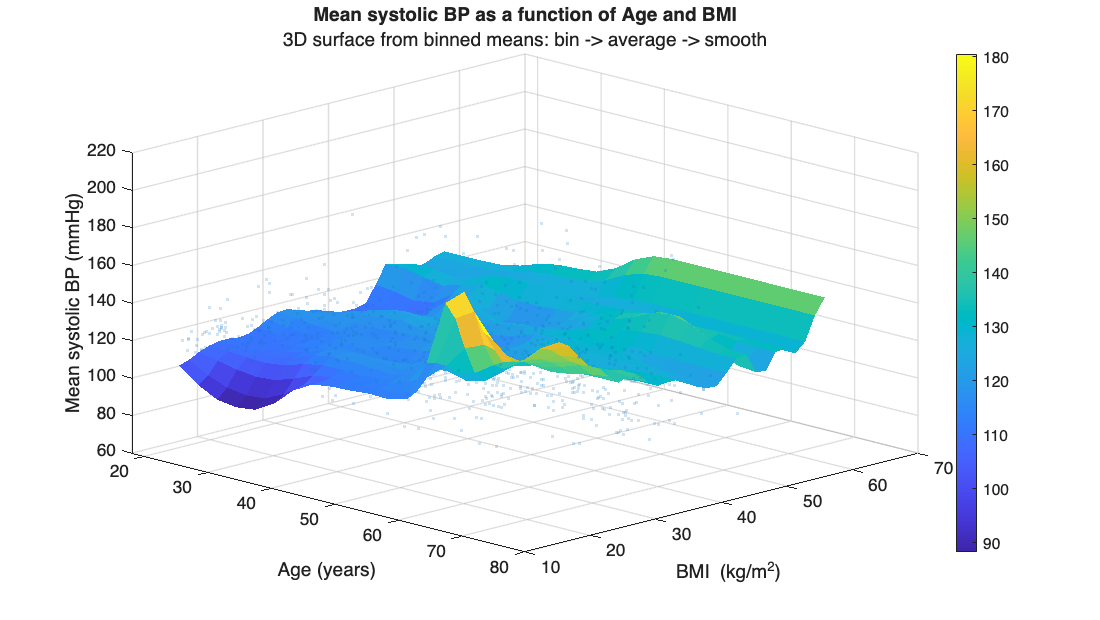

%% 3D surface: mean SysBP as a function of Age and BMI

T3 = rmmissing(Core, "DataVariables", ["Age","BMI","SysBP"]);

% Choose age and BMI bin edges. These control the resolution of the surface:
% finer bins capture more detail but can become noisy (lots of big spiky peaks) if some bins are sparse.
ageEdges = 18:3:81;
bmiEdges = 15:1.5:57;

[ageBin, ageCenters] = bin1(T3.Age, ageEdges);
[bmiBin, bmiCenters] = bin1(T3.BMI, bmiEdges);

% Here, we select for data that falls in the pre-defined bins.
ok = ~isnan(ageBin) & ~isnan(bmiBin);
ageBin = ageBin(ok);
bmiBin = bmiBin(ok);
sys    = T3.SysBP(ok);

% Compute mean systolic BP in each (ageBin, bmiBin) cell.
S = accumarray([ageBin, bmiBin], sys, ...
    [numel(ageCenters), numel(bmiCenters)], @mean, NaN);

% Fill gaps and smooth slightly along both dimensions to make it look good
S = fillmissing(S, "nearest", 1);
S = fillmissing(S, "nearest", 2);
S = smoothdata(S, 1, "gaussian", 5);
S = smoothdata(S, 2, "gaussian", 5);

[AGE, BMI] = meshgrid(ageCenters, bmiCenters);

f = newFig("3D surface", [1100 620]);


surf(AGE, BMI, S', "EdgeColor","none");
xlabel("Age (years)");
ylabel("BMI (kg/m^2)");
zlabel("Mean systolic BP (mmHg)");
title("Mean systolic BP as a function of Age and BMI", "FontWeight","bold");
subtitleIfAvailable("3D surface from binned means: bin -> average -> smooth");
colorbar;
grid on;
view(45, 25);

hold on;
scatter3(T3.Age, T3.BMI, T3.SysBP, 8, ...
    "filled", "MarkerFaceAlpha", 0.2, "MarkerEdgeAlpha", 0.2);
hold off;

## **Extra dataset example: Diet (daily energy intake)**

The NHANES diet component records 24-hour food recall information. In this lecture we work with one of the simpler diet tables: a “Day 1 totals” file where each row already summarizes one participant’s first recall day (total kcal, protein, carbohydrate, sugar, fat). This means the table is already at the **person level**, so we can join it directly to our `Core` table on `SEQN`.

This example highlights two ideas:

- How to bring in an additional component table (Diet) and line it up with our existing demographic and exam variables.

- How to explore a new variable (daily energy intake) using (i) a histogram to view the distribution, (ii) a scatter plot to relate intake to BMI and age, and (iii) a grouped bar chart of mean calories by BMI category.

In real analyses we would worry about multiple recall days and survey weights; here we keep it simple and focus on the mechanics of **joining tables and making sensible plots**.

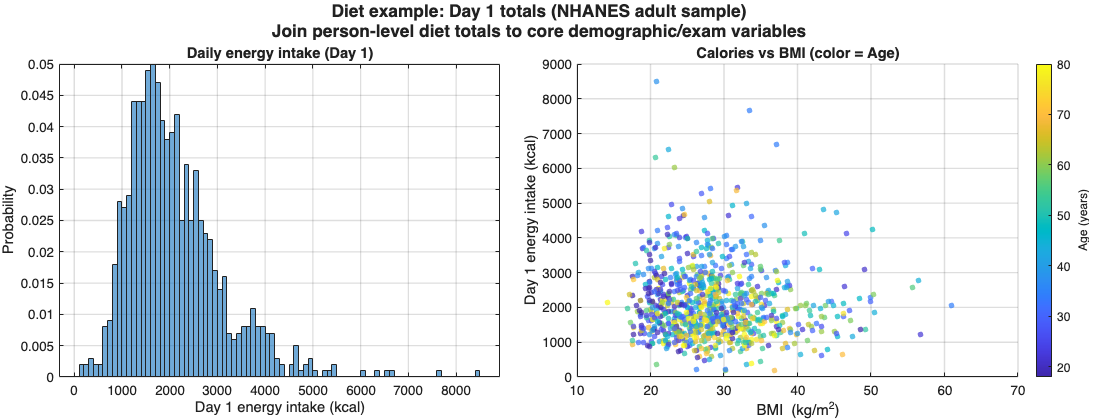


% Read a Day 1 diet table with person-level totals for key nutrients.
% DR1TKCAL = total energy intake (kcal) on Day 1.
diet = readKaggleCsv(fullfile(DATA_DIR, "diet.csv"), ...
    ["SEQN","DR1TKCAL","DR1TPROT","DR1TCARB","DR1TSUGR","DR1TTFAT"]);

% Join diet totals to the Core table (one row per adult participant).
% We use an inner join so we only keep participants who have both Core
% variables and Day 1 diet data.
Diet = innerjoin(Core(:, ["SEQN","Age","Sex","BMI","BMIclass"]), ...
                 diet, "Keys", "SEQN");

f = newFig("Diet: calories", [1100 420]);
tl = tiledlayout(f, 1, 2, "TileSpacing", "compact");
tl.Padding = "tight";

% Histogram of Day 1 energy intake
nexttile;
histogram(Diet.DR1TKCAL, "BinWidth", 100, "Normalization", "probability");
xlabel("Day 1 energy intake (kcal)");
ylabel("Probability");
grid on;
title("Daily energy intake (Day 1)", "FontWeight", "bold");

% Scatter: calories vs BMI, color-coded by age
nexttile;
scatter(Diet.BMI, Diet.DR1TKCAL, 18, Diet.Age, ...
    "filled", "MarkerFaceAlpha", 0.7);
xlabel("BMI (kg/m^2)");
ylabel("Day 1 energy intake (kcal)");
grid on;

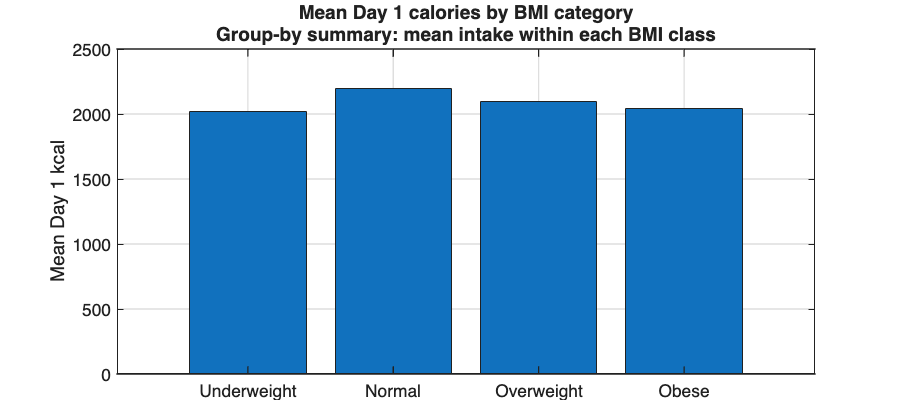

title("Calories vs BMI (color = Age)", "FontWeight", "bold");
cb = colorbar;
cb.Label.String = "Age (years)";

title(tl, { ...
    "Diet example: Day 1 totals (NHANES adult sample)", ...
    "Join person-level diet totals to core demographic/exam variables" ...
}, "FontWeight", "bold");

drawnow;

%% Mean calories by BMI category

% Group by BMI class and compute mean Day 1 calories within each category.
Gcal = groupsummary(Diet, "BMIclass", "mean", "DR1TKCAL");


f = newFig("Diet: mean calories by BMI class", [900 420]);
bar(Gcal.BMIclass, Gcal.mean_DR1TKCAL);
ylabel("Mean Day 1 kcal");
grid on;
title({"Mean Day 1 calories by BMI category", ...
       "Group-by summary: mean intake within each BMI class"}, ...
      "FontWeight", "bold");
set(gca, "XTickLabelRotation", 0);

drawnow;


## Extra dataset example: Medications (drug-level to person-level)

The NHANES medications files are stored at the drug level: each row is one reported prescription for a participant. A single person can appear in many rows if they take multiple medications. To use this information alongside our person-level Core table, we first compress the drug-level file into a summary per participant and then merge that summary back.

The steps are:

- Start from the drug-level rows in the medications file and clean obvious placeholder codes or blank drug names.

- For each participant (each SEQN), count how many distinct prescription drugs they report. This gives a simple measure of “medication burden.”

- Create a person-level table with one row per participant and this count, and join it back to Core so we can relate medication use to age and other variables.

The first plot shows the distribution of number of medications per person. Most adults report zero or one prescription, and the probability drops off quickly as the count increases. A small tail of participants are on many medications, which is typical in older or sicker populations.

The second plot looks at “polypharmacy,” defined here as taking five or more medications, by age decade. The bars rise steadily from younger to older age groups, illustrating how the proportion of people with high medication burden increases with age.

The third plot returns to the original drug-level table and shows the top ten most common medications by name. Many of these are familiar chronic-disease drugs (for example antihypertensives, statins, and diabetes medications), which helps connect the abstract counts back to real-world treatments.

Together, these plots walk through a common pattern in health data: start with many rows per person (drug-level records), create a person-level summary, merge it into a core table, and then visualize both the overall distribution and how it varies across clinically meaningful subgroups.

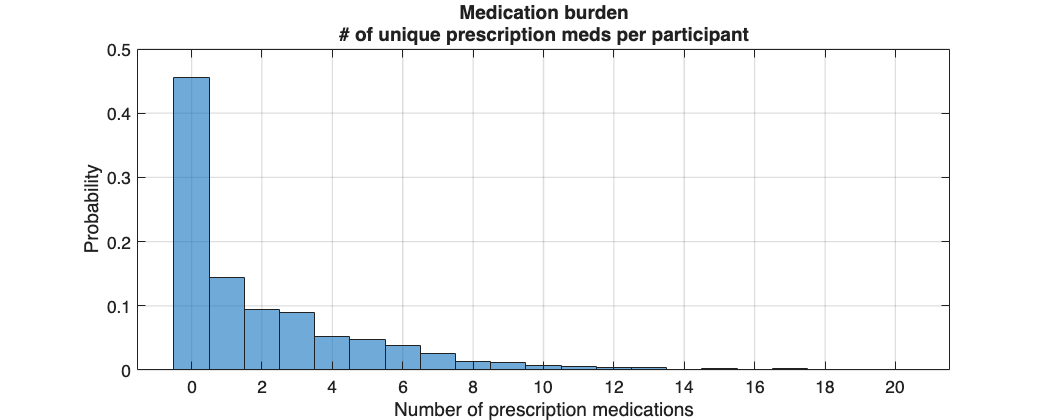

% Read a medications table where each row is one reported prescription.
% RXDDRUG: drug name/code
% RXDCOUNT/RXDUSE are available but not used in this simple example.
med = readKaggleCsv(fullfile(DATA_DIR, "medications.csv"), ...
    ["SEQN","RXDDRUG","RXDCOUNT","RXDUSE"]);

% Clean up obvious placeholders and empty names so we do not treat them as
% real drugs when counting.
drug = string(med.RXDDRUG);
isBad = ismissing(drug) | strlength(strtrim(drug)) == 0 | drug == "99999";
med = med(~isBad, :);
med.RXDDRUG = string(med.RXDDRUG);

% Person-level summary: count the number of unique prescription drugs for
% each participant.
[Gmed, ~] = findgroups(med.SEQN);
uniqueSeqn = splitapply(@(x) x(1), med.SEQN, Gmed);
numMeds    = splitapply(@(x) numel(unique(x)), med.RXDDRUG, Gmed);
MedsPerson = table(uniqueSeqn, numMeds, ...
    'VariableNames', {'SEQN','NumMeds'});
CoreM = outerjoin(Core, MedsPerson, ...
    "Keys", "SEQN", "MergeKeys", true, "Type", "left");
CoreM.NumMeds(isnan(CoreM.NumMeds)) = 0;

% Compute distribution
f = newFig("Medications: distribution", [1050 420]);
histogram(CoreM.NumMeds, "BinMethod", "integers", "Normalization", "probability");
xlabel("Number of prescription medications");
ylabel("Probability");
grid on;
title({"Medication burden", ...
       "# of unique prescription meds per participant"}, ...
      "FontWeight", "bold");

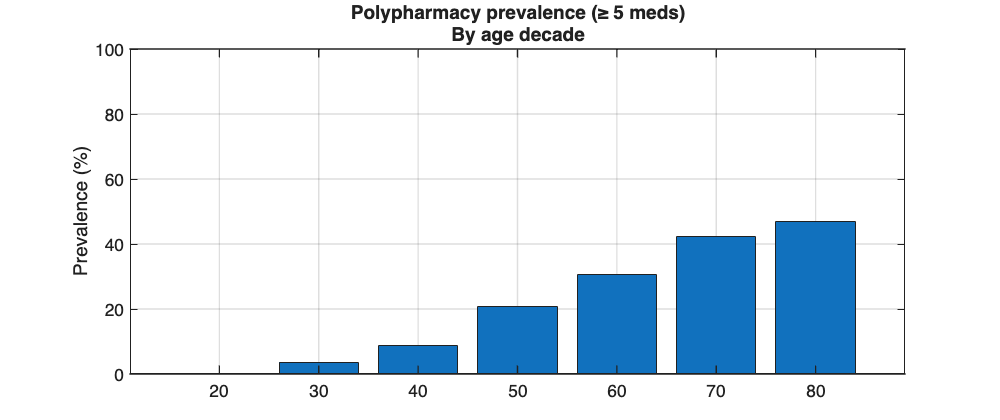


drawnow;

%% Polypharmacy prevalence (>= 5 meds) by age decade. First we create categories:
ageDec = 10 * floor(CoreM.Age / 10);
ageDec(ageDec < 20) = 20;
ageDec(ageDec > 80) = 80;
CoreM.AgeDecade = categorical(ageDec);

% Then we define polypharmacy and compute prevalence within each decade.
CoreM.Polypharm = CoreM.NumMeds >= 5;
Gpoly = groupsummary(CoreM, "AgeDecade", "mean", "Polypharm");

f = newFig("Polypharmacy by age decade", [1000 420]);
bar(Gpoly.AgeDecade, 100 * Gpoly.mean_Polypharm);
ylabel("Prevalence (%)");
ylim([0 100]);
grid on;
title({"Polypharmacy prevalence (≥ 5 meds)", ...
       "By age decade"}, ...
      "FontWeight", "bold");
set(gca, "XTickLabelRotation", 0);

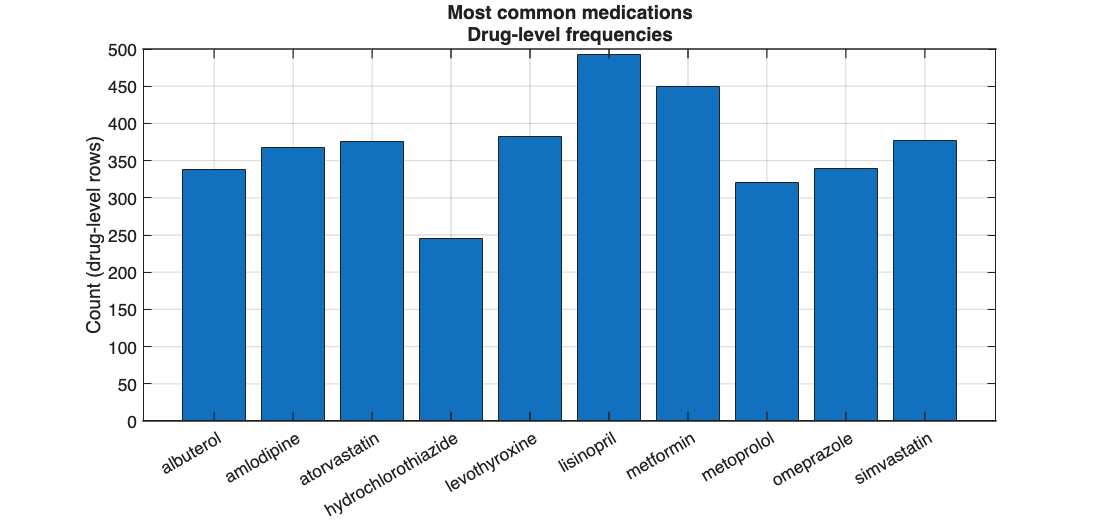


drawnow;

% Let's compute the top 10 most common medications:

drugLower = lower(strtrim(string(med.RXDDRUG)));

if exist("groupcounts", "file") == 2
    [drugCounts, drugNames] = groupcounts(drugLower);
else
    [drugNames, ~, ic] = unique(drugLower);
    drugCounts = accumarray(ic, 1);
end

[drugCounts, idx] = sort(drugCounts, "descend");
drugNames = drugNames(idx);

topK = min(10, numel(drugNames));

f = newFig("Top medications", [1100 520]);
bar(categorical(drugNames(1:topK)), drugCounts(1:topK));
ylabel("Count (drug-level rows)");
grid on;
title({"Most common medications", ...
       "Drug-level frequencies"}, ...
      "FontWeight", "bold");
xtickangle(30);

drawnow;

## **Scalar volume data and the MRI example**

### **What is scalar volume data?**

Many data sets in science and engineering live on a 3-D grid. At each point in the grid you store a single scalar value (temperature, density, intensity, etc.). This is called **scalar volume data**: a 3-D array of numbers, together with x/y/z coordinates for each voxel. Examples include MRI or CT scans, temperature inside a solid, or pressure in a fluid simulation.

In contrast, **vector volume data** stores multiple values per point (for example, the three components of velocity), which needs different visualization tools. For scalar volumes, the workhorses are:

- **Slice planes**: cut the volume with a plane and color the slice by the scalar values.

- **Contour slices**: draw contour lines in a slice showing where the field takes equal values.

- **Isosurfaces**: build a 3-D surface from all points where the scalar field equals a chosen value (like a 3-D contour surface).

MRI data is a textbook scalar volume. Each voxel stores an intensity proportional to signal from that location in the body. MATLAB ships with a sample MRI head volume (`load mri`), which we will use to demonstrate:

- how a familiar 2-D MRI slice sits inside a 3-D volume, and

- how isosurfaces and isocaps can turn the volume into an interactive 3-D object you can rotate, zoom, and explore.

### MRI slice + contour slice

We start with the most familiar view of an MRI volume: a single axial slice. This is just one 2-D plane from the 3-D array, displayed as a grayscale image.

To connect this to volume visualization, we then show the **same slice** as a contour plot. Contour lines trace out regions where the intensity is equal, just like elevation contours on a topographic map.

These two plots tell the same story in different languages:

- the image emphasizes anatomy and fine texture,

- the contour slice emphasizes level sets and shape.

Together they reinforce the idea that the MRI volume is a 3-D scalar field, and a slice is just one plane through that field.

% MRI scalar volume: slice image and contour slice

% Built-in sample MRI head volume: D is 128x128x1x27
load mri % Load the data
V = squeeze(D); % Get rid of extra dimension
sliceIdx = 14; %choose a slice of MRI data

figure("Name","MRI slice + contour", "Units","pixels", "Position",[100 100 1050 420]);
tl = tiledlayout(1, 2, "TileSpacing","compact"); tl.Padding = "tight";

% Image slice
ax1 = nexttile;
imagesc(ax1, V(:,:,sliceIdx));
axis(ax1, "image");
ax1.XTick = []; ax1.YTick = [];
colormap(ax1, map);
title(ax1, sprintf("Axial MRI slice (index %d)", sliceIdx), "FontWeight","bold");

% Contour slice
ax2 = nexttile;
contourf(ax2, V(:,:,sliceIdx), 12);
axis(ax2, "image");
axis(ax2, "ij");
ax2.XTick = []; ax2.YTick = [];
colormap(ax2, parula);
colorbar(ax2);
title(ax2, "Same slice as contour plot", "FontWeight","bold");

title(tl, ["Scalar volume view: one MRI slice in two styles", ...
           "Gray image for anatomy; contours for equal-intensity structure"], ...
      "FontWeight","bold");


drawnow;


### **3-D contour slices**

Unlike a 2-D image, a contour slice is a **3-D object**: a contour plot drawn on a plane in 3-D space. We can place several contour slices at different z-positions inside the volume and then rotate the whole figure in 3-D.

For scalar volume data like MRI, 3-D contour slices give a “stacked slice” view: each slice shows level sets of intensity, and the stack reveals how structures evolve along the head.

- The volume is still a 3-D array of intensities; each contour slice is just one plane through that array.

- Because the slices live in 3-D, you can rotate, zoom, and pan to see how contours on different slices line up.

- The number of contour levels controls how much detail you see; too many levels can be visually noisy.

%% MRI scalar volume: 3-D contour slices

load mri
V = squeeze(D);

figure("Name","MRI 3-D contour slices", ...
       "Units","pixels", "Position",[100 100 700 600]);

cm = parula(256);
colormap(cm);

zSlices = [3 9 15 21]; % We choose to visualize 4 slices

% Draw contour slices in 3-D. The [] for x and y means "use voxel indices".
% The last argument (8) is the number of contour levels.
contourslice(V, [], [], zSlices, 8);

axis tight;
daspect([1 1 0.4]);
view(3); %3D iso view
box on;
xlabel("X (voxel index)");
ylabel("Y (voxel index)");
zlabel("Slice index");

title({"MRI volume: 3-D contour slices", ...
       "Stacked contour planes show how intensity patterns change across slices"}, ...
      "FontWeight","bold");

### **MRI volume: isosurfaces and isocaps**

A slice shows one plane through the volume. To understand the **3-D shape** of structures, we can use **isosurfaces**.

An isosurface is the 3-D analog of a contour line: it is the surface formed by all points where the scalar field takes on a particular value. For MRI, an isosurface at a medium intensity can hug the outer boundary of the head, giving a “3-D skull/skin” shell.

On its own, the shell can feel context-free. **Isocaps** fix that by adding colored caps where the volume has been cut away. The cap shows interior slice values mapped to color, so you see both the outer shape and a cross-section of what lives inside.

- rotate the head with the mouse to see how the isosurface wraps around the slices,

- zoom in on regions where the cap reveals interior tissue,

- experiment with different isosurface thresholds to see how the shell grows and shrinks.

%% MRI scalar volume: isosurface + isocaps

load mri
V = squeeze(D);
Vs = smooth3(V, "box", 5);

isoVal = 5;

f = figure("Name","MRI isosurface + isocaps", ...
           "Units","pixels", ...
           "Position",[100 100 800 620]);
ax = axes(f);
hold(ax, "on");
colormap(ax, map);

% Isosurface: outer shell of the head.
hIso = patch(ax, isosurface(Vs, isoVal), ...
    "FaceColor", [1 0.78 0.68], ...
    "EdgeColor", "none");
isonormals(Vs, hIso);

% Isocaps: show interior data where the isosurface is cut away
hCap = patch(ax, isocaps(V, isoVal), ...
    "FaceColor", "interp", ...
    "EdgeColor", "none");

% Boiler-plate Camera setup
view(ax, 35, 25);
axis(ax, "tight");
daspect(ax, [1 1 0.4]);
ax.Visible = "off";
camlight(ax, "headlight");
camlight(ax, "right");
lighting(ax, "gouraud");

title(ax, { ...
    "MRI head volume: isosurface + isocaps", ...
    "Isosurface shows outer shape; isocaps reveal interior slices" ...
}, "FontWeight", "bold");

hold(ax, "off");

drawnow;

## **Exporting figures for slides and reports**

When you finish a plotting session, MATLAB can export figures at a consistent resolution for PowerPoint, Keynote, or LaTeX. The function `exportgraphics` writes a single figure to disk using settings you control.

For classroom or research slides, good defaults are:

- Export to **PNG**

- Use **200–300 DPI** so text stays crisp 

- Prefer **wide figure sizes **(fits on slides easier)

A practical tip: set your random seed (`rng(...)`) so any sampling in your workflow produces the same figures each time you regenerate them. Deterministic output makes your handouts consistent.

Below, we create an output folder and export *all currently open figures* in one loop.

% OUT_DIR = fullfile(pwd, "figures_lecture2");
% if ~exist(OUT_DIR, "dir")
%     mkdir(OUT_DIR);
% end
% 
% figs = findall(0, "Type", "figure");
% for k = 1:numel(figs)
%     fname = fullfile(OUT_DIR, sprintf("Lecture2_%02d.png", k));
%     exportgraphics(figs(k), fname, "Resolution", 200);
% end

% fprintf("Exported %d figures to: %s\n", numel(figs), OUT_DIR);